### Load neural data

m1 = XZ98;
m2 = XZ91;
MName1 = m1.AnimalID;
MName2 = m2.AnimalID;
m1_neural = m1.MS{2}.FiltTraces(1801:end,logical(m1.MS{2}.goodCellVec)); % remove first 2 min
m2_neural = m2.MS{2}.FiltTraces(1801:end,logical(m2.MS{2}.goodCellVec));
m1_tstamp = m1.TimeStamp.Ts{2}.Ms(1801:end);
m2_tstamp = m2.TimeStamp.Ts{2}.Ms(1801:end);
m1_neural_bined = BinData(m1_neural, 5, 'mean'); % bin to 1/3 s
m2_neural_bined = BinData(m2_neural, 5, 'mean');
m1_tstamp_bined = BinData(m1_tstamp, 5, 'mean');
m2_tstamp_bined = BinData(m2_tstamp, 5, 'mean');

### Load tracking data

tracks_matrix_raw = h5read('PairQD6.h5','/tracks');
disp(size(tracks_matrix_raw))

       38757           5           2           2



% frames x nodes x 2 (x,y) x tracks
% nose earR earL tailbase body
% fill NAs
tracks_matrix_raw = fillmissing(tracks_matrix_raw, 'movmean', 7, 1);

### Read timestamp and bin data, trucate tracking to match length, align timestamp

tstamp_raw = csvread('PairQD6.csv', 1);
tstamp_raw = tstamp_raw(size(tstamp_raw,1)-size(tracks_matrix_raw,1)+1:end,2); % match video
% match neural data (remove first x minutes)
neural_starts_here = find(tstamp_raw>=m1_tstamp(1),1)

neural_starts_here =         3312


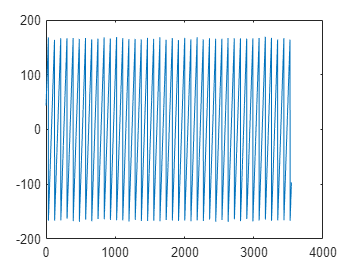

tracks_matrix = tracks_matrix_raw(neural_starts_here:end,:,:,:);
tstamp = tstamp_raw(neural_starts_here:end);

% bin Data
tracks_bined = BinData(tracks_matrix, 10, 'mean');
time_bined = BinData(tstamp, 10, 'mean');

% timestamp map
[idx1,idx2,tdifference] = TStampAlign(time_bined,m1_tstamp_bined);
figure, plot(tdifference);

if length(idx2) ~= length(idx1)
   idx1 = idx1(1:min(length(idx1), length(idx2)));
   idx2 = idx2(1:min(length(idx1), length(idx2)));
end

m1_tstamp_bined = m1_tstamp_bined(idx2,:);
m2_tstamp_bined = m2_tstamp_bined(idx2,:);
m1_neural_bined = m1_neural_bined(idx2,:);
m2_neural_bined = m2_neural_bined(idx2,:);
tracks_bined = tracks_bined(idx1,:,:,:);
time_bined = time_bined(idx1);


% find approximate head position by finding mid point between nose and body
head_coord = 1/2*(tracks_bined(:,1,:,:) + tracks_bined(:,5,:,:));

### Quadrant position states

qcenter = [295,249]; %[ycenter, xcenter]
qcode = [head_coord(:,:,1,1)<=qcenter(1), head_coord(:,:,2,1) > qcenter(2), head_coord(:,:,1,2)<=qcenter(1),...
    head_coord(:,:,2,2)>qcenter(2)];
qseries = [qcode(:,1)+qcode(:,2)*2,qcode(:,3)+qcode(:,4)*2];
qseries(qseries==1) = 4; qseries(qseries == 0) = 1;
q_diff = diff(qseries,[],2);
p_time_spent_together = sum(q_diff == 0)/length(q_diff)

p_time_spent_together =          0.216704288939052


p_time_spent_neighbor = sum(or(abs(q_diff)==1,abs(q_diff)==3))/length(q_diff)

p_time_spent_neighbor =          0.557279909706546


p_time_spent_diag = sum(abs(q_diff)==2)/length(q_diff)

p_time_spent_diag =          0.226015801354402


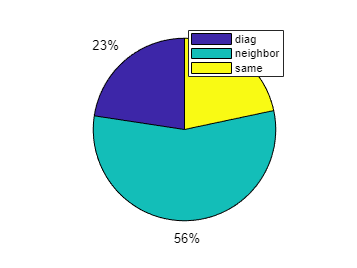

figure, pie([p_time_spent_diag,p_time_spent_neighbor,p_time_spent_together]);legend({'diag','neighbor','same'})

### Get PLSC and overlay plot with quadrant state

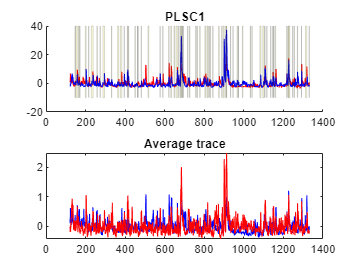

[PLS1, PLS2, USV] = GetPLSC(m1_neural_bined, m2_neural_bined);
figure, ax = subplot(2,1,1,'NextPlot','add'); plot(ax,m1_tstamp_bined/1000,PLS1(:,1),'r'); plot(ax,m2_tstamp_bined/1000,PLS2(:,1),'b')
% find same quadrant time point
same_q_t = find(qseries(:,1) == qseries(:,2));
% find consecutive bouts (apply threshold > )
onset_t = cat(1,1,find(diff(same_q_t)>2)+1);
offset_t = same_q_t([onset_t(2:end)-1;length(same_q_t)]);
onset_t = time_bined(same_q_t(onset_t))/1000;
offset_t = time_bined(offset_t)/1000;
% patch same quadrant period
for i = 1:length(onset_t)
    patch(ax,[onset_t(i),offset_t(i),offset_t(i),onset_t(i)],[ax.YLim(1),ax.YLim(1),ax.YLim(2),ax.YLim(2)],'y','FaceAlpha',0.15, 'EdgeAlpha',0.14);
end
title('PLSC1');
% plot average plot
subplot(2,1,2);plot(m1_tstamp_bined/1000, mean(m1_neural_bined,2),'b-'), hold on, plot(m2_tstamp_bined/1000, mean(m2_neural_bined,2),'r-');
title('Average trace');

### Prepare training/test set

S_idx = find(qseries(:,1) == qseries(:,2)); % same index
N_idx = find(or(abs(qseries(:,1)-qseries(:,2)) == 1, abs(qseries(:,1)-qseries(:,2)) == 3)); % neighbor index
D_idx = find(abs(qseries(:,1)-qseries(:,2)) == 2); % diagonal index
idxs = {S_idx,N_idx,D_idx};
state_names = {'Same','Neighbor','Diag'};
Y = zeros(length(idx2),1); Y(S_idx) = 1; Y(N_idx) = 2; Y(D_idx) = 3;
% prepare training/test set
m1_neural_bined = zscore(m1_neural_bined);
m2_neural_bined = zscore(m2_neural_bined);

### One vs all

kfold = 10;
cvspace = 45;
f = figure;
for kd = 1:length(idxs)
    Y_temp = Y; Y_temp(cat(1,idxs{setdiff(1:length(idxs),kd)})) = 0; Y_temp(idxs{kd}) = 1;
%     part_temp = cvpartition(Y_temp, 'KFold', fold);
    [perform_1, perform_shifted_1] = OnevOneDecoder(m1_neural_bined, Y_temp, kfold, cvspace,'logistic','accuracy');
    [perform_2, perform_shifted_2] = OnevOneDecoder(m2_neural_bined, Y_temp, kfold, cvspace,'logistic','accuracy');
    [perform_3, perform_shifted_3] = OnevOneDecoder([m1_neural_bined,m2_neural_bined], Y_temp, kfold, cvspace,'logistic','accuracy');
    perform = [perform_1,perform_2,perform_3];
    perform_shifted = [perform_shifted_1, perform_shifted_2, perform_shifted_3];
    a = subplot(1,3,kd,'Parent',f);
    XZBoxPlot({perform, perform_shifted},[1,2,3,1,2,3],[1,3,5,2,4,6],...
        {MName1,MName2,'Both',[MName1,'\_shuffled'],[MName2,'\_shuffled'],'Both\_shuffled'},[],a);
     randguess_ = max([length(idxs{kd})/length(Y_temp),1-length(idxs{kd})/length(Y_temp)]);
     line(a, a.XLim, [randguess_, randguess_],'LineStyle','--');
     title([state_names{kd},'-v-All']); ylabel('Accuracy');
end

### One vs one

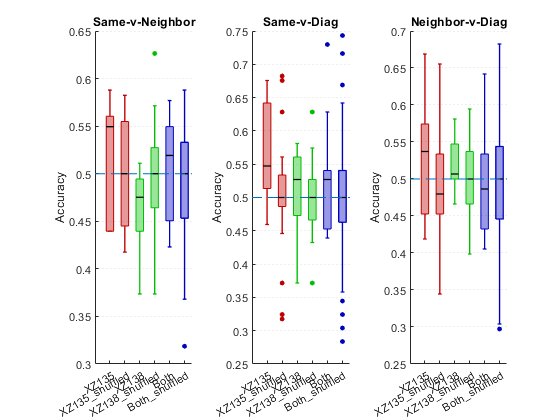

randguess_ = 0.5000

randguess_ = 0.5000

randguess_ = 0.5000

combines = nchoosek(1:3,2);
f = figure;
for kd = 1:size(combines,1)
    [mlen,midx] = min([length(idxs{combines(kd,1)}),length(idxs{combines(kd,2)})]);
    dsample_idx = datasample(idxs{setdiff(combines(kd,:),combines(kd,midx))}, mlen,'Replace',false);
    m1_neural_bined_dvn = m1_neural_bined(cat(1,idxs{combines(kd,midx)}, dsample_idx));
    m2_neural_bined_dvn = m2_neural_bined(cat(1,idxs{combines(kd,midx)}, dsample_idx));
    % same vs neighbor
    Y_temp = Y;Y_temp(idxs{combines(kd,1)}) = 1; Y_temp(idxs{combines(kd,2)}) = 0; Y_temp = Y_temp(cat(1,idxs{combines(kd,midx)}, dsample_idx));
%     part_temp = cvpartition(Y_temp, 'KFold', fold);
    perform = [];
    perform_shifted = [];
    [perform_1, perform_shifted_1] = OnevOneDecoder(m1_neural_bined_dvn, Y_temp, kfold, cvspace,'logistic','accuracy');
    [perform_2, perform_shifted_2] = OnevOneDecoder(m2_neural_bined_dvn, Y_temp, kfold, cvspace,'logistic','accuracy');
    [perform_3, perform_shifted_3] = OnevOneDecoder([m1_neural_bined_dvn,m2_neural_bined_dvn], Y_temp, kfold, cvspace,'logistic','accuracy');
    perform = [perform_1,perform_2,perform_3];
    perform_shifted = [perform_shifted_1, perform_shifted_2, perform_shifted_3];
    a = subplot(1,3,kd,'Parent',f);
    XZBoxPlot({perform, perform_shifted},[1,2,3,1,2,3],[1,3,5,2,4,6],...
        {MName1,MName2,'Both',[MName1,'\_shuffled'],[MName2,'\_shuffled'],'Both\_shuffled'},[],a);
%     randguess_ = max([length(idxs{combines(kd,1)})/length(Y_temp),1-length(idxs{combines(kd,1)})/length(Y_temp)]);
    randguess_ = 0.5;
    line(a, a.XLim, [randguess_, randguess_],'LineStyle','--');
    title([state_names{combines(kd,1)},'-v-',state_names{combines(kd,2)}]); ylabel('Accuracy');
end 

### Behavior

% count the number of same->neighbor and neighbor->same change for each
% construct group state vector 1=same 2=neighbor 3=diag
gqseries = zeros(size(qseries,1),1);
gqseries(idxs{1}) = 1; gqseries(idxs{2}) = 2; gqseries(idxs{3}) = 3; unique(gqseries)

ans =      1
     2
     3


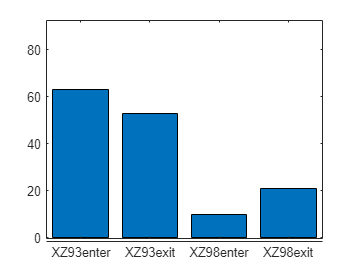

[gonset, goffset] = FindConsecutiveOnsetOffset(gqseries);
transit_cell = {cell(1,2), cell(1,2)}; % mouse1, mouse2, enter, exit
for i = 1:numel(gonset{1}) % for each same onset
    onset_t = gonset{1}(i);
    if onset_t == 1
        continue
    end
    menter = find(qseries(onset_t-1,:) ~= qseries(onset_t,:));
    for k = menter
        transit_cell{k}{1} = [transit_cell{k}{1}; gonset{1}(i)];
    end
    offset_t = goffset{1}(i);
    if offset_t == size(qseries,1)
        continue
    end
        mexit = find(qseries(offset_t,:) ~= qseries(offset_t+1,:));
    for k = mexit
        transit_cell{k}{2} = [transit_cell{k}{2}; goffset{1}(i)];
    end
end
figure;bar(categorical({[MName1,'enter'],[MName1,'exit'],[MName2,'enter'],[MName2,'exit']}), [numel(transit_cell{1}{1}),numel(transit_cell{1}{2}),numel(transit_cell{2}{1}),numel(transit_cell{2}{2})]);

### Find joint spatial print for cells

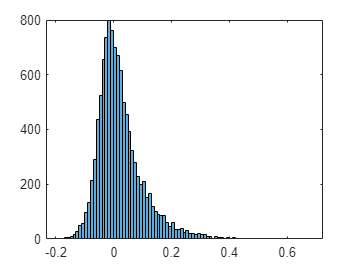

kn = 4;
corrmat = corr(m1_neural_bined, m2_neural_bined);
figure, histogram(corrmat(:));

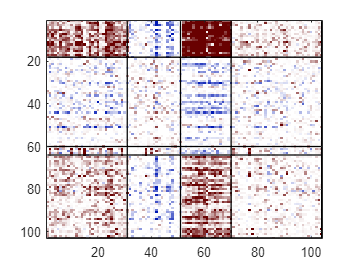

rng(0);
idx1 = kmeans(corrmat, kn);
idx2 = kmeans(corrmat', kn);
[~,c_order1] = sort(idx1);
[~,c_order2] = sort(idx2);
imagesc(corrmat(c_order1, c_order2));colormap(red_blue_colormap);clim([-0.15,0.2])
hold on
for i = 1:numel(unique(idx1))
    line([1,size(corrmat,2)], sum(idx1<=i)*ones(1,2),'Color','black','LineWidth',1);
end
for i = 1:numel(unique(idx2))
    line(sum(idx2<=i)*ones(1,2), [1,size(corrmat,1)],'Color','black','LineWidth',1);
end

### Plot cell activity map (cluster)

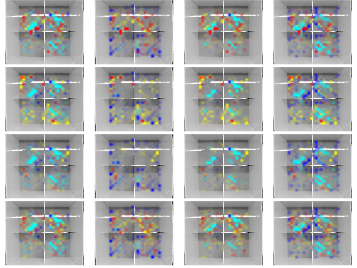

% divide into 20x50 grid
load('E:\MiniscopeData(processed)\Quadrant assay\Behavior_videos&TrackingProjects\red_colormap.mat');
% arena = imread('PairQD6_arena.tif');
xgrid = linspace(1,size(arena,1),28);
ygrid = linspace(1,size(arena,2),32);
nrow= 4; ncol=4;
dist_threshold = 80;
f = figure;
cluster1 = sort(unique(idx1));
cluster2 = sort(unique(idx2));
for k = 1:numel(cluster1)
for j = 1:numel(cluster2)
    grid_count1 = zeros(32,28);
    grid_neuron1 = zeros(32,28);
    grid_count2 = zeros(32,28);
    grid_neuron2 = zeros(32,28);
    grid_count3 = zeros(32,28); % counts for interaction
    grid_neuron3 = zeros(32,28); % counts for interaction
    grid_count4 = zeros(32,28); % counts for interaction
    grid_neuron4 = zeros(32,28);
    avg_trace1 = mean(m1_neural_bined(:,find(idx1==cluster1(k))),2); % red
    avg_trace2 = mean(m2_neural_bined(:,find(idx2==cluster2(j))),2); % blue  
    for i = 1:size(head_coord,1)
        current_x1 = head_coord(i,1,2,1);
        current_y1 = head_coord(i,1,1,1);
        current_x2 = head_coord(i,1,2,2);
        current_y2 = head_coord(i,1,1,2);
        xidx1 = find(xgrid>=current_x1,1);
        yidx1 = find(ygrid>=current_y1,1);
        xidx2 = find(xgrid>=current_x2,1);
        yidx2 = find(ygrid>=current_y2,1);
        cur_dist = sqrt((current_x2-current_x1)^2+(current_y1-current_y2)^2);
        if gqseries(i) == 1 & cur_dist < dist_threshold
            grid_neuron3(yidx1,xidx1) = grid_neuron3(yidx1,xidx1) + avg_trace1(i);
            grid_count3(yidx1,xidx1) = grid_count3(yidx1,xidx1) + 1;
            grid_neuron4(yidx2,xidx2) = grid_neuron4(yidx2,xidx2) + avg_trace2(i);
            grid_count4(yidx2,xidx2) = grid_count4(yidx2,xidx2) + 1;
            continue
        end

        grid_neuron1(yidx1,xidx1) = grid_neuron1(yidx1,xidx1) + avg_trace1(i);
        grid_count1(yidx1,xidx1) = grid_count1(yidx1,xidx1) + 1;
        grid_neuron2(yidx2,xidx2) = grid_neuron2(yidx2,xidx2) + avg_trace2(i);
        grid_count2(yidx2,xidx2) = grid_count2(yidx2,xidx2) + 1;

    end
    max13 = quantile((grid_neuron1+grid_neuron3)./(grid_count1+grid_count3),1,'all');
    max24 = quantile((grid_neuron2+grid_neuron4)./(grid_count2+grid_count4),1,'all');
    avg_neuron1 = grid_neuron1./grid_count1;
    avg_neuron2 = grid_neuron2./grid_count2;
    avg_neuron3 = grid_neuron3./grid_count3;
    avg_neuron4 = grid_neuron4./grid_count4;
    avg_neuron1(isnan(avg_neuron1)) = 0;
    avg_neuron2(isnan(avg_neuron2)) = 0;
    avg_neuron3(isnan(avg_neuron3)) = 0;
    avg_neuron4(isnan(avg_neuron4)) = 0;
    avg_neuron3 = uint8(255*mat2gray(avg_neuron3,[0,max13]));
    avg_neuron4 = uint8(255*mat2gray(avg_neuron4,[0,max24]));
    avg_neuron1 = uint8(255*mat2gray(avg_neuron1,[0,max13]));
    avg_neuron2 = uint8(255*mat2gray(avg_neuron2,[0,max24]));
    

%     grid_rgb = cat(3, avg_neuron1, zeros(size(avg_neuron1)), avg_neuron2);
%     f= figure; ax = axes('Parent',f,'NextPlot','add');
    ax = subplot(nrow,ncol,j+(k-1)*ncol,'Parent',f,'NextPlot','add');
%     title(['M1',num2str(k),'-M2',num2str(j)]);
    imshow(arena,'Parent',ax);
    red = cat(3, ones(size(arena,[1,2])), zeros(size(arena,[1,2])), zeros(size(arena,[1,2])));
    blue = cat(3, zeros(size(arena,[1,2])), zeros(size(arena,[1,2])), ones(size(arena,[1,2])));
    yellow = cat(3, ones(size(arena,[1,2])), ones(size(arena,[1,2])), zeros(size(arena,[1,2])));
    cyan = cat(3, zeros(size(arena,[1,2])), ones(size(arena,[1,2])), ones(size(arena,[1,2])));
    y = imshow(yellow,'Parent',ax);
    set(y,'AlphaData', imresize(permute(avg_neuron1,[2,1]), size(arena,[1,2])));
    b = imshow(blue,'Parent',ax);
    set(b,'AlphaData', imresize(permute(avg_neuron2,[2,1]), size(arena,[1,2])));
    r = imshow(red,'Parent',ax);
    set(r,'AlphaData',imresize(permute(avg_neuron3,[2,1]), size(arena,[1,2])));
    c = imshow(cyan, 'Parent', ax);
    set(c,'AlphaData',imresize(permute(avg_neuron4,[2,1]), size(arena,[1,2])));
%     imagesc(ax, imresize(avg_grid,size(arena,[1,2])),'AlphaDataMapping','scaled');
%     colormap(ax,red_colormap);clim([0,Inf]);
    
end
end
ha = get(gcf,'children');
for j = 1:length(ha)
    axpos = [mod(ncol*nrow-j,ncol)/ncol, 1-1/nrow-floor((nrow*ncol-j)/ncol)/nrow, 1/ncol, 1/nrow];
    set(ha(j),'position',axpos);
end

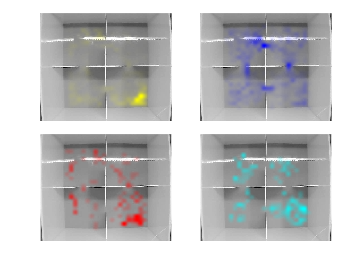

m1_grid_count = grid_count1+grid_count3; m1_grid_count = m1_grid_count/sum(m1_grid_count(:));
m2_grid_count = grid_count2+grid_count4; m2_grid_count = m2_grid_count/sum(m2_grid_count(:));
m12_grid_count = grid_count3; m12_grid_count = m12_grid_count/sum(grid_count1(:)+grid_count3(:));
m21_grid_count = grid_count4; m21_grid_count = m21_grid_count/sum(grid_count2(:)+grid_count4(:));
m1_grid_count(isnan(m1_grid_count)) = 0; m2_grid_count(isnan(m2_grid_count)) = 0;
m12_grid_count(isnan(m12_grid_count)) = 0; m21_grid_count(isnan(m21_grid_count)) = 0;
m12_grid_count = uint8(255*mat2gray(m12_grid_count,[0,max(m12_grid_count,[],'all')]));
m21_grid_count = uint8(255*mat2gray(m21_grid_count,[0,max(m21_grid_count,[],'all')]));
m1_grid_count = uint8(255*mat2gray(m1_grid_count,[0,max(m1_grid_count,[],'all')]));
m2_grid_count = uint8(255*mat2gray(m2_grid_count,[0,max(m2_grid_count,[],'all')]));


f = figure;
ax = subplot('position',[0.1,0.55,0.4,0.4],'NextPlot','add','Parent',f); imshow(arena,'Parent',ax);
y = imshow(yellow, 'Parent', ax);
set(y, 'AlphaData', imresize(permute(m1_grid_count,[2,1]), size(arena,[1,2])));
ax = subplot('Position',[0.55,0.55,0.4,0.4],'NextPlot','add','Parent',f); imshow(arena,'Parent',ax);
b = imshow(blue, 'Parent', ax);
set(b, 'AlphaData', imresize(permute(m2_grid_count,[2,1]), size(arena,[1,2])))
ax = subplot('position',[0.1,0.1,0.4,0.4],'NextPlot','add','Parent',f); imshow(arena,'Parent',ax);
r = imshow(red, 'Parent', ax);
set(r, 'AlphaData', imresize(permute(m12_grid_count,[2,1]), size(arena,[1,2])));
ax = subplot('Position',[0.55,0.1,0.4,0.4],'NextPlot','add','Parent',f); imshow(arena,'Parent',ax);
c = imshow(cyan, 'Parent', ax);
set(c, 'AlphaData', imresize(permute(m21_grid_count,[2,1]), size(arena,[1,2])))

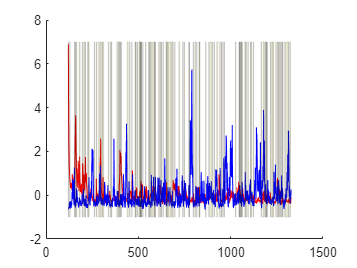

% plot selected clusters
f = figure; ax = axes('Parent',f, 'NextPlot','add');
plot(m1_tstamp_bined/1000, mean(m1_neural_bined(:,find(idx1==5)),2),'r-');
plot(m2_tstamp_bined/1000, mean(m2_neural_bined(:,find(idx2==4)),2),'b-');
onset_t = gonset{1};
offset_t = goffset{2};
for i = 1:length(gonset{1})
    onset_t = time_bined(gonset{1}(i));
    offset_t = time_bined(goffset{1}(i));
    patch([onset_t,offset_t,offset_t,onset_t]/1000,[ax.YLim(1),ax.YLim(1),ax.YLim(2),ax.YLim(2)],'y','FaceAlpha',0.15, 'EdgeAlpha',0.14);
end

### Plot PLSC map

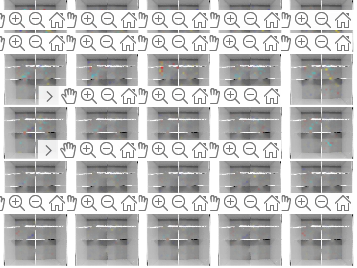

% divide into 20x50 grid
load('E:\MiniscopeData(processed)\Quadrant assay\Behavior_videos&TrackingProjects\red_colormap.mat');
xgrid = linspace(1,size(arena,1),28);
ygrid = linspace(1,size(arena,2),32);
nrow= 5; ncol=5;
dist_threshold = 80;
f = figure;
PLS_max1 = 0; PLS_max2 = 0; % for color lim
for k = 1:25
    grid_count1 = zeros(32,28);
    grid_neuron1 = zeros(32,28);
    grid_count2 = zeros(32,28);
    grid_neuron2 = zeros(32,28);
    grid_count3 = zeros(32,28); % counts for interaction
    grid_neuron3 = zeros(32,28); % counts for interaction
    grid_count4 = zeros(32,28); % counts for interaction
    grid_neuron4 = zeros(32,28);
    avg_trace1 = (PLS1(:,k)-mean(PLS1(:,k))).^2; % red
    avg_trace2 = (PLS2(:,k)-mean(PLS2(:,k))).^2; % blue
    for i = 1:size(head_coord,1)
        current_x1 = head_coord(i,1,2,1);
        current_y1 = head_coord(i,1,1,1);
        current_x2 = head_coord(i,1,2,2);
        current_y2 = head_coord(i,1,1,2);
        xidx1 = find(xgrid>=current_x1,1);
        yidx1 = find(ygrid>=current_y1,1);
        xidx2 = find(xgrid>=current_x2,1);
        yidx2 = find(ygrid>=current_y2,1);
        cur_dist = sqrt((current_x2-current_x1)^2+(current_y1-current_y2)^2);
        if gqseries(i) == 1 & cur_dist < dist_threshold
            grid_neuron3(yidx1,xidx1) = grid_neuron3(yidx1,xidx1) + avg_trace1(i);
            grid_count3(yidx1,xidx1) = grid_count3(yidx1,xidx1) + 1;
            grid_neuron4(yidx2,xidx2) = grid_neuron4(yidx2,xidx2) + avg_trace2(i);
            grid_count4(yidx2,xidx2) = grid_count4(yidx2,xidx2) + 1;
            continue
        end

        grid_neuron1(yidx1,xidx1) = grid_neuron1(yidx1,xidx1) + avg_trace1(i);
        grid_count1(yidx1,xidx1) = grid_count1(yidx1,xidx1) + 1;
        grid_neuron2(yidx2,xidx2) = grid_neuron2(yidx2,xidx2) + avg_trace2(i);
        grid_count2(yidx2,xidx2) = grid_count2(yidx2,xidx2) + 1;

    end
    avg_neuron1 = grid_neuron1./grid_count1;
    avg_neuron2 = grid_neuron2./grid_count2;
    avg_neuron3 = grid_neuron3./grid_count3;
    avg_neuron4 = grid_neuron4./grid_count4;
    avg_neuron1(isnan(avg_neuron1)) = 0;
    avg_neuron2(isnan(avg_neuron2)) = 0;
    avg_neuron3(isnan(avg_neuron3)) = 0;
    avg_neuron4(isnan(avg_neuron4)) = 0;

    if k == 1
        PLS_max1 = quantile((grid_neuron1+grid_neuron3)./(grid_count1+grid_count3),0.98,"all");
        PLS_max2 = quantile((grid_neuron2+grid_neuron4)./(grid_count2+grid_count4),0.98,'all');
    end
%     avg_neuron3 = uint8(255*mat2gray(avg_neuron3,[0,PLS_max1]));
%     avg_neuron4 = uint8(255*mat2gray(avg_neuron4,[0,PLS_max2]));
%     avg_neuron1 = uint8(255*mat2gray(avg_neuron1,[0,PLS_max1]));
%     avg_neuron2 = uint8(255*mat2gray(avg_neuron2,[0,PLS_max2]));
    
    max13 = quantile((grid_neuron1+grid_neuron3)./(grid_count1+grid_count3),0.98,'all');
    max24 = quantile((grid_neuron2+grid_neuron4)./(grid_count2+grid_count4),0.98,'all');
    avg_neuron3 = uint8(255*mat2gray(avg_neuron3,[0,max13]));
    avg_neuron4 = uint8(255*mat2gray(avg_neuron4,[0,max24]));
    avg_neuron1 = uint8(255*mat2gray(avg_neuron1,[0,max13]));
    avg_neuron2 = uint8(255*mat2gray(avg_neuron2,[0,max24]));
    

%     grid_rgb = cat(3, avg_neuron1, zeros(size(avg_neuron1)), avg_neuron2);
%     f= figure; ax = axes('Parent',f,'NextPlot','add');
    ax = subplot(nrow,ncol,k,'Parent',f,'NextPlot','add');
%     title(['M1',num2str(k),'-M2',num2str(j)]);
    imshow(arena,'Parent',ax);
    red = cat(3, ones(size(arena,[1,2])), zeros(size(arena,[1,2])), zeros(size(arena,[1,2])));
    blue = cat(3, zeros(size(arena,[1,2])), zeros(size(arena,[1,2])), ones(size(arena,[1,2])));
    yellow = cat(3, ones(size(arena,[1,2])), ones(size(arena,[1,2])), zeros(size(arena,[1,2])));
    cyan = cat(3, zeros(size(arena,[1,2])), ones(size(arena,[1,2])), ones(size(arena,[1,2])));
    y = imshow(yellow,'Parent',ax);
    set(y,'AlphaData', imresize(permute(avg_neuron1,[2,1]), size(arena,[1,2])));
    b = imshow(blue,'Parent',ax);
    set(b,'AlphaData', imresize(permute(avg_neuron2,[2,1]), size(arena,[1,2])));
    c = imshow(cyan, 'Parent', ax);
    set(c,'AlphaData',imresize(permute(avg_neuron4,[2,1]), size(arena,[1,2])));
    r = imshow(red,'Parent',ax);
    set(r,'AlphaData',imresize(permute(avg_neuron3,[2,1]), size(arena,[1,2])));
%     imagesc(ax, imresize(avg_grid,size(arena,[1,2])),'AlphaDataMapping','scaled');
%     colormap(ax,red_colormap);clim([0,Inf]);
    
end
ha = get(gcf,'children');
for j = 1:length(ha)
    axpos = [mod(ncol*nrow-j,ncol)/ncol, 1-1/nrow-floor((nrow*ncol-j)/ncol)/nrow, 1/ncol, 1/nrow];
    set(ha(j),'position',axpos);
end